clear all;
% --------------------------------------------------------------
% Parameters
% --------------------------------------------------------------
a1 = 1.2272 %[cm2] Area of outlet pipe 1

a1 = 1.2272

a2 = 1.2272 %[cm2] Area of outlet pipe 2

a2 = 1.2272

a3 = 1.2272 %[cm2] Area of outlet pipe 3

a3 = 1.2272

a4 = 1.2272 %[cm2] Area of outlet pipe 4

a4 = 1.2272

A1 = 380.1327 %[cm2] Cross sectional area of tank 1

A1 = 380.1327

A2 = 380.1327 %[cm2] Cross sectional area of tank 2

A2 = 380.1327

A3 = 380.1327 %[cm2] Cross sectional area of tank 3

A3 = 380.1327

A4 = 380.1327 %[cm2] Cross sectional area of tank 4

A4 = 380.1327

gamma1 = 0.45; % Flow distribution constant. Valve 1
gamma2 = 0.40; % Flow distribution constant. Valve 2
g = 981; %[cm/s2] The acceleration of gravity
rho = 1.00; %[g/cm3] Density of water
p = [a1; a2; a3; a4; A1; A2; A3; A4; gamma1; gamma2; g; rho];
% --------------------------------------------------------------



% --------------------------------------------------------------
% Simulation scenario
% --------------------------------------------------------------
t0 = 0.0; % [s] Initial time
tf = 20*60; % [s] Final time
m10 = 0.0; % [g] Liquid mass in tank 1 at time t0
m20 = 0.0; % [g] Liquid mass in tank 2 at time t0
m30 = 0.0; % [g] Liquid mass in tank 3 at time t0
m40 = 0.0; % [g] Liquid mass in tank 4 at time t0
F1 = 300; % [cm3/s] Flow rate from pump 1
F2 = 300; % [cm3/s] Flow rate from pump 2
x0 = [m10; m20; m30; m40];
u = [F1; F2]

u =    300
   300


% --------------------------------------------------------------

% --------------------------------------------------------------
% Compute the solution / Simulate
% --------------------------------------------------------------
% Solve the system of differential equations
[T,X] = ode15s(@FourTankSystem,[t0 tf],x0,[],u,p);
%函数作为参数传递可以使任务变得模板化，ode15就是想针对不同的model

% --------------------------------------------------------------
% help variables
[nT,nX] = size(X);
a = p(1:4,1)';
A = p(5:8,1)';

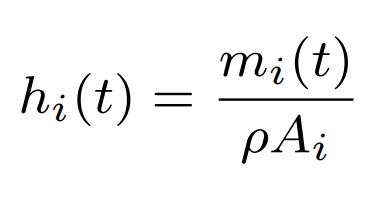

% Compute the measured variables
H = zeros(nT,nX);
for i=1:nT
H(i,:) = X(i,:)./(rho*A);
end

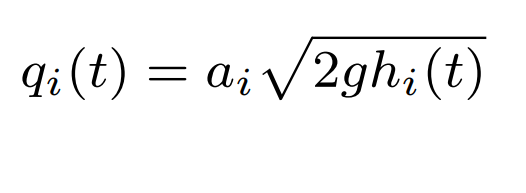

% Compute the flows out of each tank
Qout = zeros(nT,nX);
for i=1:nT
Qout(i,:) = a.*sqrt(2*g*H(i,:));
end
% --------------------------------------------------------------

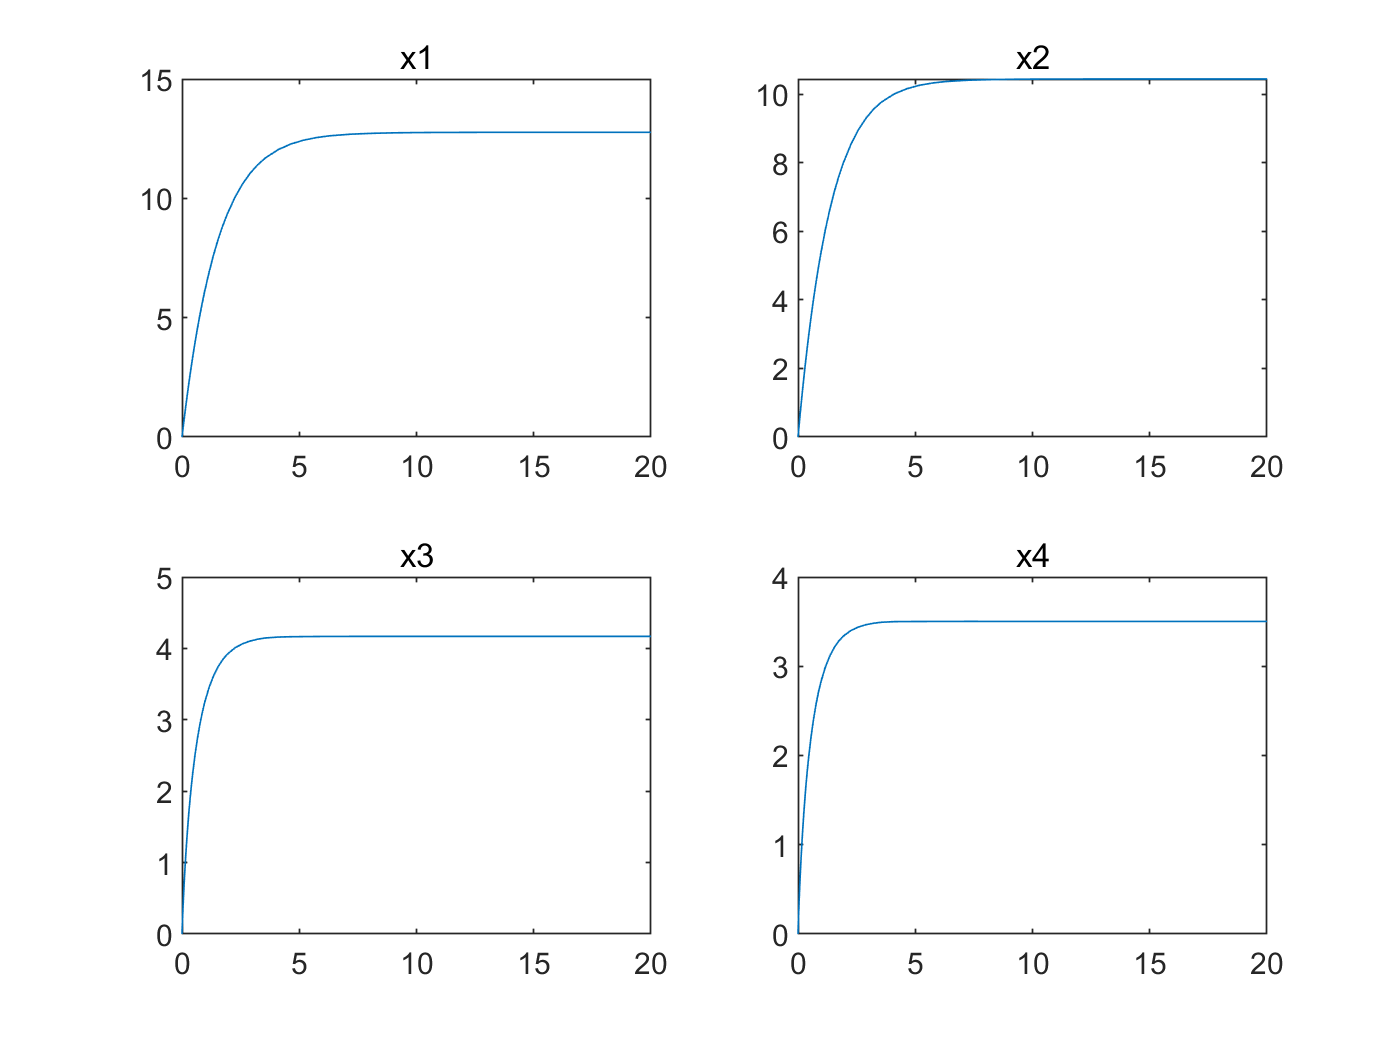

%plot the x
%输入时cm3,g，作为状态值的m1,m2,m3,m4需要表示为kg，output值的h表示为cm 时间从s变为min
figure
subplot(2,2,1)
plot(T/60,X(:,1)/1e3)
title('x1')
subplot(2,2,2)
plot(T/60,X(:,2)/1e3)
title('x2')
subplot(2,2,3)
plot(T/60,X(:,3)/1e3)
title('x3')
subplot(2,2,4)
plot(T/60,X(:,4)/1e3)
title('x4')

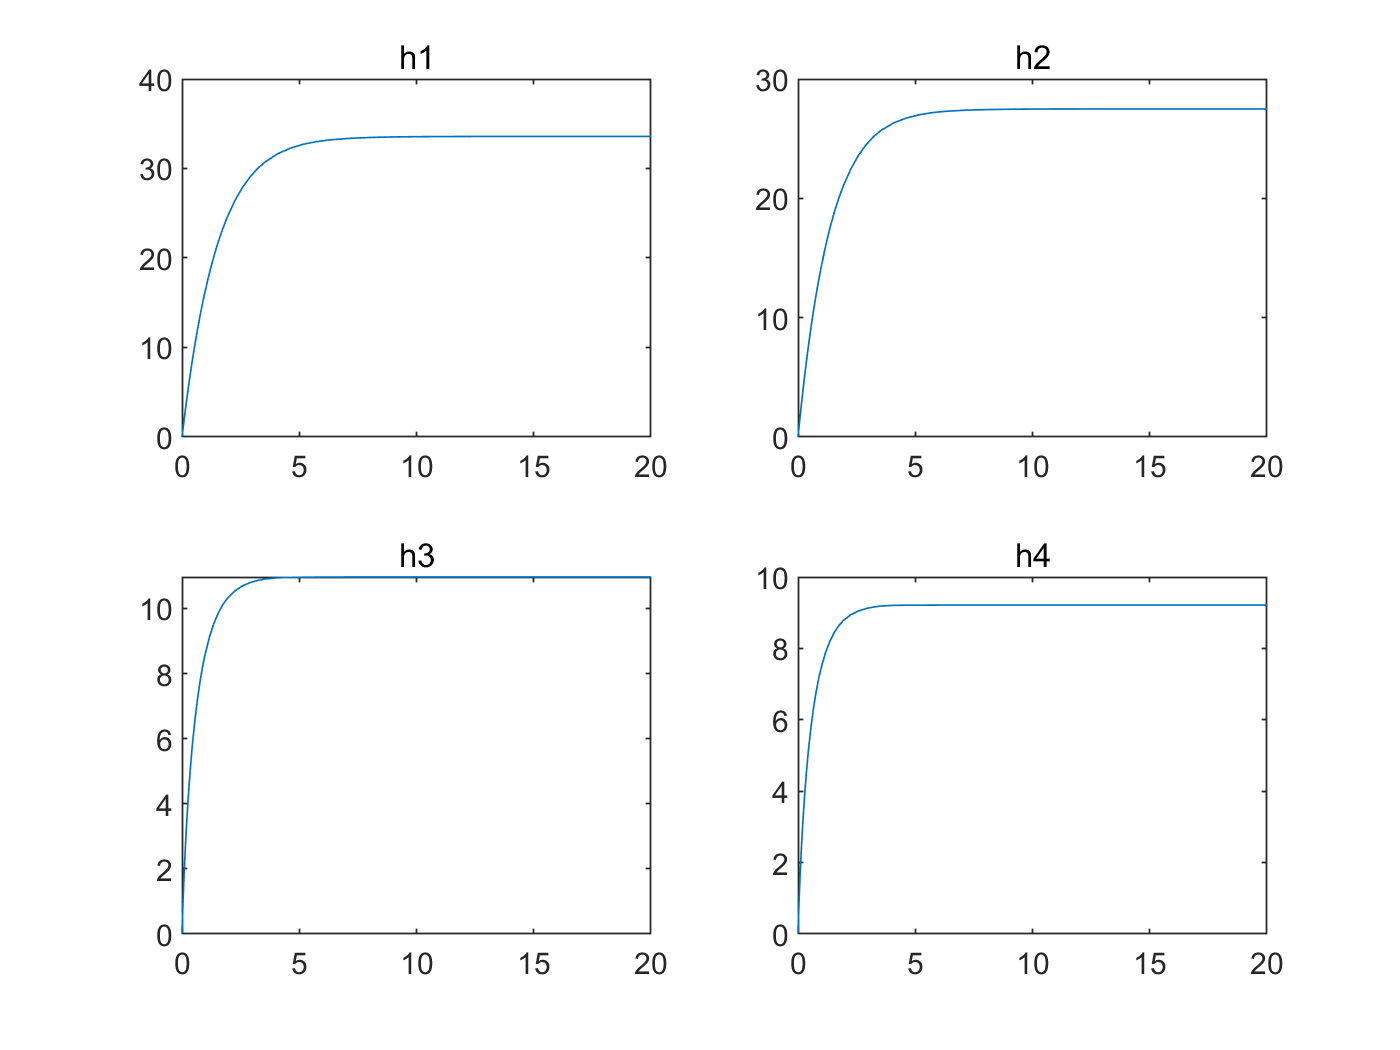

%plot the h
figure
subplot(2,2,1)
plot(T/60,H(:,1))
title('h1')
subplot(2,2,2)
plot(T/60,H(:,2))
title('h2')
subplot(2,2,3)
plot(T/60,H(:,3))
title('h3')
subplot(2,2,4)
plot(T/60,H(:,4))
title('h4')

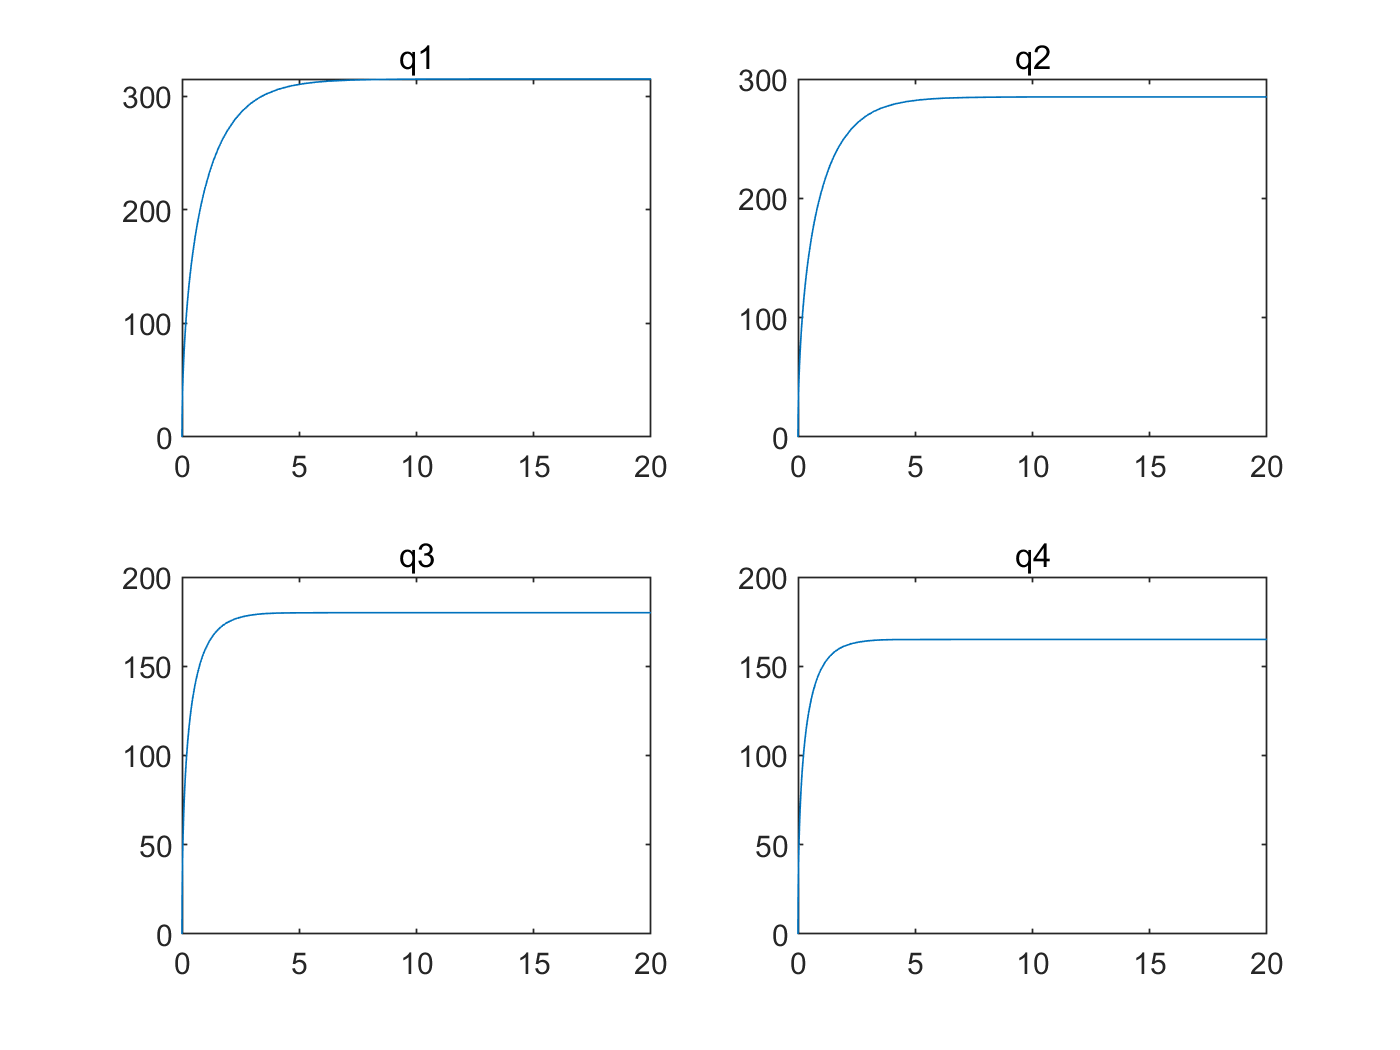

%plot the q
figure
subplot(2,2,1)
plot(T/60,Qout(:,1))
title('q1')
subplot(2,2,2)
plot(T/60,Qout(:,2))
title('q2')
subplot(2,2,3)
plot(T/60,Qout(:,3))
title('q3')
subplot(2,2,4)
plot(T/60,Qout(:,4))
title('q4')

% --------------------------------------------------------------
% Simulation scenario
% --------------------------------------------------------------
%离散系统的前向仿真
%不必纠结和slides中的图标不同，因为slides中的input是变化的，之前的input是不变的300
%而离散的系统我们就可以在不同的时间加入不同的input了，在这里我们的u是是300，300，持续1200列

t0 = 0.0; % [s] Initial time
tf = 20*60; % [s] Final time
m10 = 0.0; % [g] Liquid mass in tank 1 at time t0
m20 = 0.0; % [g] Liquid mass in tank 2 at time t0
m30 = 0.0; % [g] Liquid mass in tank 3 at time t0
m40 = 0.0; % [g] Liquid mass in tank 4 at time t0
F1 = 300; % [cm3/s] Flow rate from pump 1
F2 = 300; % [cm3/s] Flow rate from pump 2
x0 = [m10; m20; m30; m40];
u = [F1; F2]

u =    300
   300


% --------------------------------------------------------------

nx=4;%状态的个数
N=1200%差分次数

N = 1200

t=0:N-1;%一定要从0开始！！！
u=zeros(2,N);
u(1,:)=F1;
u(2,:)=F2;
X = zeros(0,nx);
T = zeros(0,1);
x(:,1) = x0;
for k = 1:N-1
y(:,k) = FourTankSystemSensor(x(:,k),p); % Sensor function
z(:,k) = FourTankSystemOutput(x(:,k),p); % Output function
[Tk,Xk] = ode15s(@FourTankSystem,[t(k) t(k+1)],x(:,k),[],u(:,k),p);%p是参数的数组
x(:,k+1) = Xk(end,:)';
T = [T; Tk];
X = [X; Xk];
end
k = N;
y(:,k) = FourTankSystemSensor(x(:,k),p);
z(:,k) = FourTankSystemOutput(x(:,k),p);
%与之前连续系统的区别，可以看到连续系统直接用ode15s模拟从0到1200的仿真，最后仿真出1200个点来
%这个离散系统是循环1200次，每一次第k到k+1秒都进行仿真，每一秒有11个点，每次取最后一个点

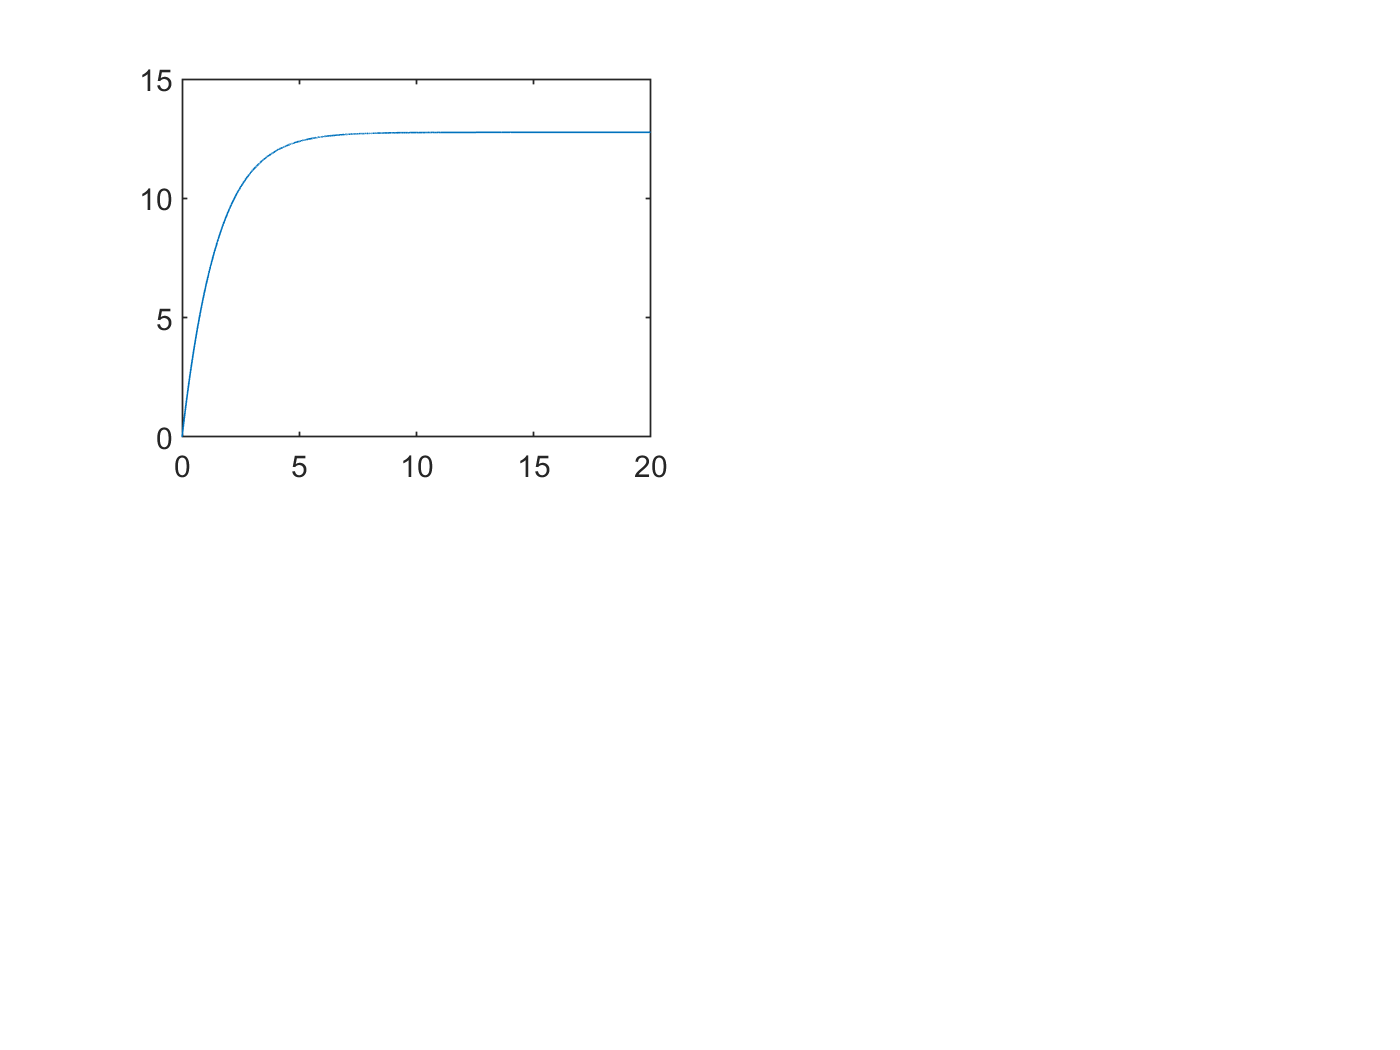

%plot x 
figure

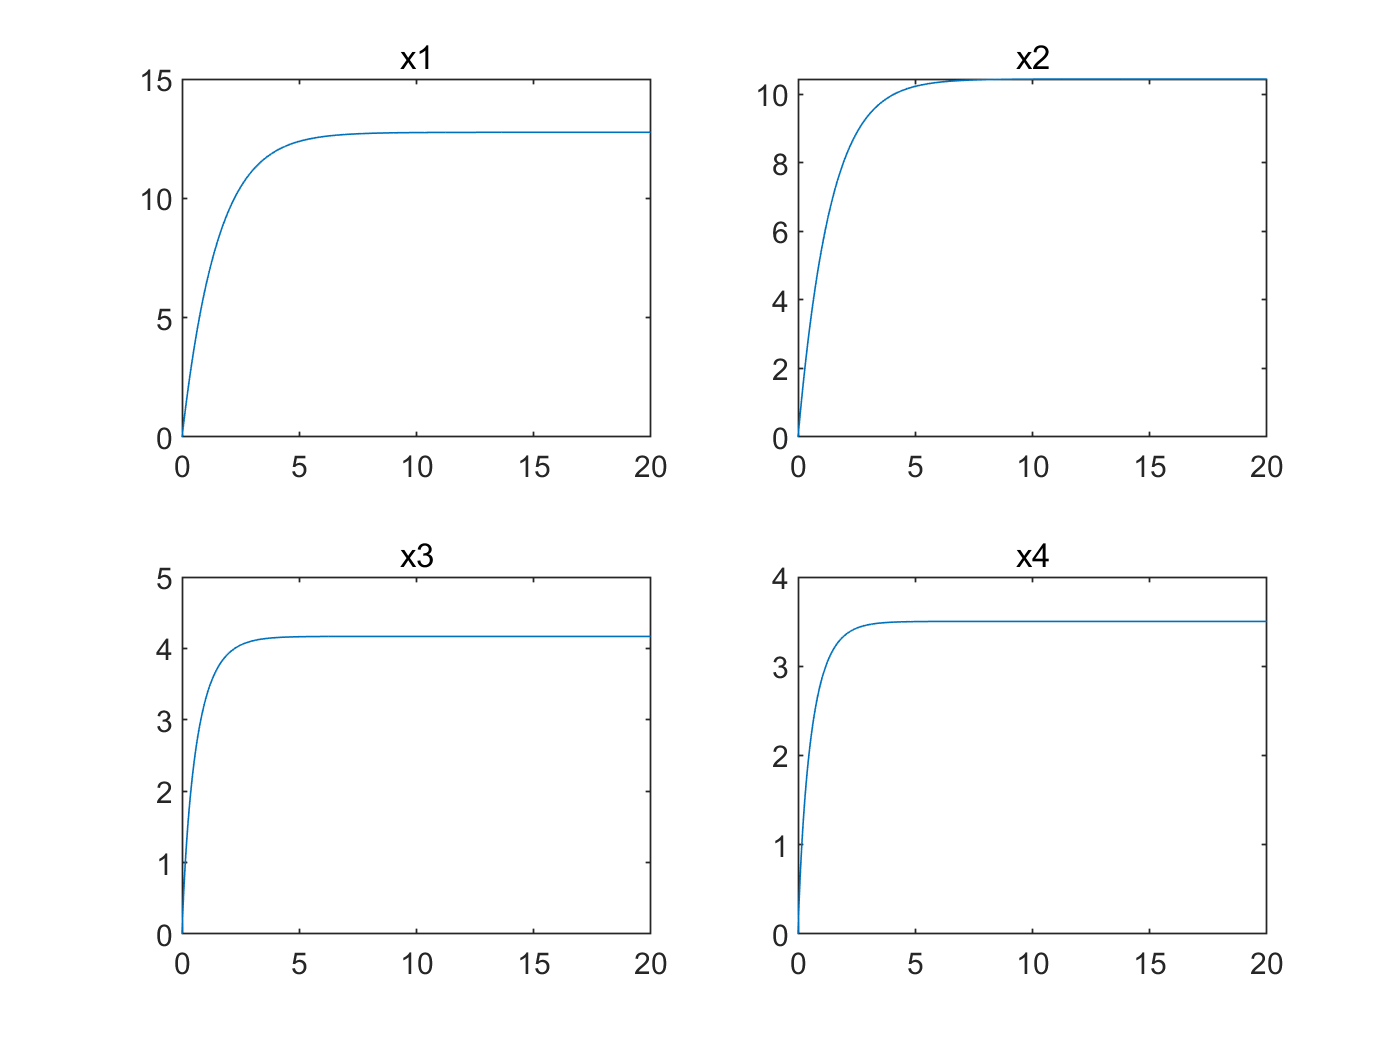

subplot(2,2,1)
plot(t/60,x(1,:)/1e3)
title('x1')
subplot(2,2,2)
plot(t/60,x(2,:)/1e3)
title('x2')
subplot(2,2,3)
plot(t/60,x(3,:)/1e3)
title('x3')
subplot(2,2,4)
plot(t/60,x(4,:)/1e3)
title('x4')